% 
% Script: predicted_vs_actual.m
%  
% Dependencies:
%   +demos/data/experiment_2_motion_primitives_corrected.mat
%   +demos/data/NS_motion_primitives.mat
%   +demos/data/exp_S.mat
%   +demos/data/exp_NS.mat
%   +demos/data/gait_library_2_corrected.mat
%   +demos/data/gait_library_S.mat
%   +demos/data/gait_library_NS.mat
%
%   +offlineanalysis/GaitPredict
%   +offlineanalysis/Gait
%
% Description: 
%   Compare experimental and predicted gait trajectories / motion
%   primitives.

% [0] == Script setup
clear; clc; close all
% Add dependencies to classpath
addpath('../');
% Configure figure tex interpreters
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');
set(0,'defaultAxesFontSize',16)

% Define gait robot states.
gait_B = [16,7,5,11,14];

% Load motion primitive (x y theta) data.
mps_H = load('data/experiment_2_motion_primitives_corrected.mat').motion_primitive_data;
mps_NS = load('data/NS_motion_primitives.mat').motion_primitive_data;

% Load experiment gait data. 
exp_S = load('data/exp_S.mat').exp_S;
exp_NS = load('data/exp_NS.mat').exp_NS;

% Load experimental gait library data. 
gait_library_H = load('data/gait_library_2_corrected.mat').gait_library_2;
gait_library_S = load('data/gait_library_S.mat').gait_library_S;
gait_library_NS = load('data/gait_library_NS.mat').gait_library_NS;

## [1] == Instantiate GaitPredict() objects for each gait permutation.

Define parameters.

exp.params.robot_name = 'orange';
exp.params.substrate = 'black mat';

% Calculate heavy sheath (H) tether predicted gait motions.
predicted_H = offlineanalysis.GaitPredict(gait_B, mps_H, exp.params);

% Calculate no sheath (NS) tether predicted gait motions.
predicted_NS = offlineanalysis.GaitPredict(gait_B, mps_NS, exp.params);

% Average the experimental motions for heavy sheath. 
for i = 1:6
    delta_poses_S((i-1)*59+1:i*59, :, :) = cat(3, exp_S(i).delta_x, exp_S(i).delta_y, exp_S(i).delta_theta);
end

gait_mps_S = zeros(length(delta_poses_S), 240,3);
gait_mps_S(:,exp_S(1).primitive_labels, :) = delta_poses_S;

averaged_S = offlineanalysis.GaitPredict(gait_B, gait_mps_S, exp.params);

for i = 1:6
    delta_poses_NS((i-1)*59+1:i*59, :, :) = cat(3, exp_NS(i).delta_x, exp_NS(i).delta_y, exp_NS(i).delta_theta);
end

gait_mps_NS = zeros(length(delta_poses_NS), 240,3);
gait_mps_NS(:,exp_NS(1).primitive_labels, :) = delta_poses_NS;

% Calculate no sheath (NS) tether averaged gait motions.
averaged_NS = offlineanalysis.GaitPredict(gait_B, gait_mps_NS, exp.params);

## [2] == Plot all motion primitives with 95% confidence intervals.

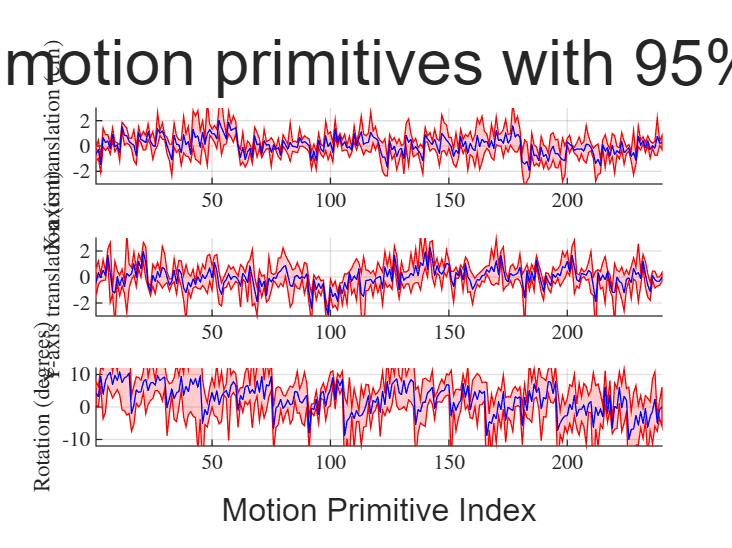

figure(1)
[pt_H, avg_motions_H, stand_devs_H] = plot_all_deviations(mps_H);
title(pt_H, 'Heavy sheath tether motion primitives with 95% confidence intervals', ...
    'FontSize', 24)

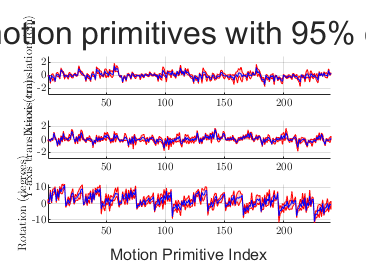


figure(2)
[pt_NS, avg_motions_NS, stand_devs_NS] = plot_all_deviations(mps_NS);
title(pt_NS, 'No sheath tether motion primitives with 95% confidence intervals', ...
    'FontSize', 24)

## [3] == Plot experimental vs. predicted gait trajectories for no sheath tethers.

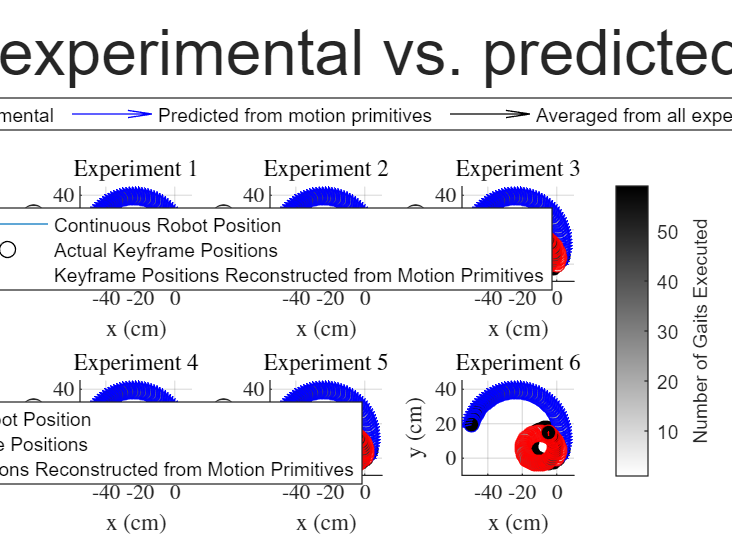

% figure(3)
% for i = 1:6
%     averaged_poses(:,:,i) = gait_library_NS(i).plot(59);
% end
% clf;
figure(3)
t=tiledlayout(2,3);
t.TileSpacing = 'tight';
t.Padding = 'compact';
title(t, 'No sheath tether experimental vs. predicted gait trajectory', 'FontSize', 24)
for i = 1:6
    nexttile;
    hold on
    averaged_poses(:,:,i) = averaged_NS.plot(59);
    ax = gca;
    ax.Children(1).Color = 	"black";
    ax.Children(2).MarkerEdgeColor = "none";

    ax.Children(3).MarkerEdgeColor = "black"; 

    predicted_poses(:,:,i) = predicted_NS.plot(59);
    ax = gca;
    ax.Children(1).Color = "blue";
    ax.Children(2).MarkerEdgeColor = "none";
    ax.Children(3).MarkerEdgeColor = "blue"; 
    ax.Children(3).MarkerEdgeAlpha = .8;

    exp_NS(i).plot;
    ax.Children(1).Color = "red";
    ax.Children(2).MarkerEdgeColor = "none";
    ax.Children(3).MarkerEdgeColor = "red"; 
    ax.Children(3).MarkerEdgeAlpha = .8;
    
    xlim([-55 10])
    ylim([-10 45])
    daspect([1 1 1]);
    colormap(flip(gray))
    title(['Experiment ', num2str(i)], 'FontWeight','bold')
    grid on
end

a = colorbar;
a.Label.String = 'Number of Gaits Executed';
a.Layout.Tile = 'east';
lgd = legend([ax.Children(1) ax.Children(5) ax.Children(9)],...
    {'Experimental', 'Predicted from motion primitives', 'Averaged from all experiments'});
lgd.Layout.Tile = 'north';
lgd.Orientation = 'horizontal';

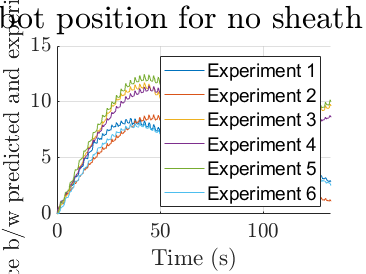

color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE"];


figure(4)
title('Error in robot position for no sheath experiments', 'FontSize', 24)
timestamps = 0:.45:295*.45;
for i = 1:6
    hold on
    diff = ((exp_NS(i).poses(1,exp_NS(i).keyframes(2:end)) - ...
            averaged_poses(1,:,i)).^2+ ...
            (exp_NS(i).poses(2,exp_NS(i).keyframes(2:end)) - ...
            averaged_poses(2,:,i)).^2).^.5;
    plot(timestamps, abs(diff - diff(1)), 'Color', color_array(i))
    xlim([0 timestamps(end)])
    lgd_str{i} = ['Experiment ', num2str(i)];
end

grid on
xlabel('Time (s)')
ylabel('Euclidean distance b/w predicted and experimental paths (cm)')
legend(lgd_str)

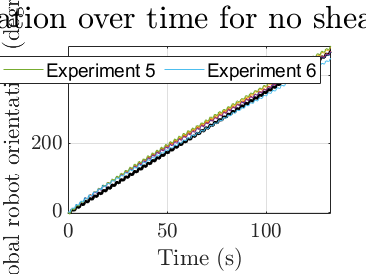



figure(5)
ang(1,:) = rad2deg(averaged_poses(3,:,i));
plot(timestamps, ang, 'k-', 'LineWidth', 2)
lgd_str{1} = 'Predicted';
for i = 1:6
    hold on
    ang(i+1,:) = exp_NS(i).poses(3,exp_NS(i).keyframes(2:end));
    ang(i+1,:) = rad2deg(ang(i+1,:)-ang(i+1,1));
    ang(i+1, ang(i+1,:)<-100) = ang(i+1,ang(i+1,:)<-100)+360;
    ang(i+1, timestamps>60 & ang(i+1,:)<200) = ang(i+1, timestamps>60 & ang(i+1,:)<200)+360;
    plot(timestamps, ang(i+1, :), 'Color', color_array(i))
    lgd_str{i+1} = ['Experiment ', num2str(i)];
end
grid on
xlim([0 timestamps(end)])
xlabel('Time (s)')
ylabel('Global robot orientation (degrees)')
lgd = legend(lgd_str);
lgd.Orientation = 'horizontal';
lgd.Location = 'north';
title('Robot orientation over time for no sheath experiments', 'FontSize', 24)
axis tight 


figure(6)
title('Error in robot orientation for no sheath experiments', 'FontSize', 24)
hold on
for i = 1:6
    plot(timestamps, ang(i+1,:) - ang(1,:), 'Color', color_array(i))
    lgd_str{i} = ['Experiment ', num2str(i)];
end
grid on
xlim([0 timestamps(end)])
xlabel('Time (s)')
ylabel('Robot orientation error $\theta_{exp} - \theta_{pred}$ (deg)')
lgd = legend(lgd_str);

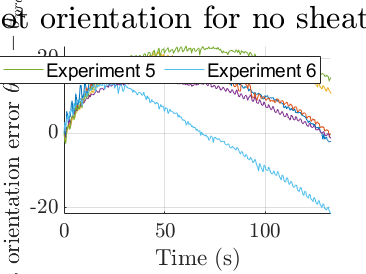

lgd.Orientation = 'horizontal';
lgd.Location = 'north';



figure
t = tiledlayout(3, 2);
t.TileSpacing = "compact";
t.Padding = 'compact';

[4] == Plot the predicted behavior with variance for each motion primitive of the base gait. 

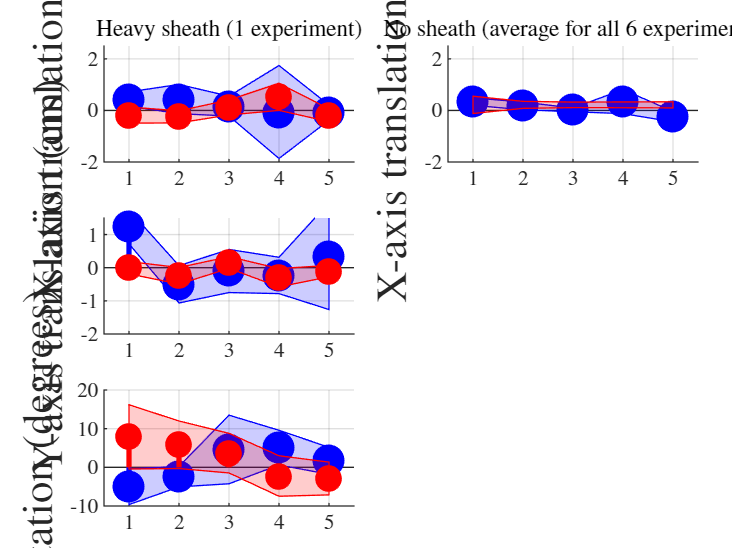

Error using stem
X must be same length as Y.

for j = 1:2
    mp_seq = gait_library_H(2).primitive_labels;
switch j
    case 1
        motion_primitive_gait_data= mps_H(:,mp_seq,:);
        gait_lib = gait_library_H(2);
        delta_poses = gait_lib.delta_poses;
        var_poses = gait_lib.var_delta_poses;
    case 2
        motion_primitive_gait_data= mps_NS(:,mp_seq,:);
        gait_lib = averaged_NS;
        delta_poses = [averaged_NS.delta_x'; averaged_NS.delta_y'; averaged_NS.delta_theta'];
        var_poses = squeeze(var(delta_poses_NS, 0, 1))';
end
% Find mean, variance, and standard deviation of data.
avg_motions = squeeze(mean(motion_primitive_gait_data, 1))';
avg_motions(3,:) = rad2deg(avg_motions(3,:));
var_motions = squeeze(var(motion_primitive_gait_data, 0, 1))';
stand_devs = var_motions.^(.5);
stand_devs(3,:) = rad2deg(stand_devs(3,:));
delta_poses(3,:) = rad2deg(delta_poses(3,:));
stand_dev_poses = var_poses.^(.5);
stand_dev_poses(3,:) = rad2deg(stand_dev_poses(3,:));

for i = 1:3
nexttile(2*(i-1)+j);
x = 1:size(avg_motions,2);
xticks(1:length(gait_B))
%xticklabels(string(predicted_gait_H(j).primitive_labels))
xlim([0.5, length(gait_B)+0.5])
switch i 
    case 1
        ylabel('X-axis translation (cm)', 'FontSize', 16)
        ylim([-2 2.5])
        if j == 1
            title('Heavy sheath (1 experiment)')
        else
            title('No sheath (average for all 6 experiments)')
        end
    case 2 
        ylabel('Y-axis translation (cm)', 'FontSize', 16)
        ylim([-2 1.5])
    case 3 
        ylabel('Rotation (degrees)', 'FontSize', 16)
        ylim([-10 20])
end

grid on 
hold on
plus_sd = avg_motions(i,:)+2*stand_devs(i,:);
minus_sd = avg_motions(i,:)-2*stand_devs(i,:);

p=fill([x fliplr(x)],[plus_sd fliplr(minus_sd)],'b','FaceAlpha',0.2, 'DisplayName',"\pm 2\sigma predicted");
p.EdgeColor = 'b';
stp = stem(x,avg_motions(i,:),'b', 'LineWidth',2,'MarkerFaceColor','b', 'MarkerSize',10,'DisplayName',"average predicted motion");
plus_sdp = delta_poses(i,:)+2*stand_dev_poses(i,:);
minus_sdp = delta_poses(i,:)-2*stand_dev_poses(i,:);
pa=fill([x fliplr(x)],[plus_sdp fliplr(minus_sdp)],'r','FaceAlpha',0.2,'DisplayName',"\pm 2\sigma actual");
pa.EdgeColor = 'r';
sta = stem(x,delta_poses(i,:),'r', 'LineWidth',2,'MarkerFaceColor','r', 'MarkerSize',8,'DisplayName',"average actual motion");

end
end

predd = avg_motions;
actt = delta_poses;


%title(t,'Predicted vs. Actual Motion for each Motion Primitive in a Gait', 'FontSize', 24)
t.XLabel.String = 'Motion primitive index';
t.XLabel.FontSize = 24;
lg = legend([stp p sta pa],'FontSize',24);
lg.Orientation = 'horizontal';
lg.NumColumns = 2;
lg.Layout.Tile = 'north';

figure
t = tiledlayout(3, 6);
t.TileSpacing = "tight";
t.Padding = 'tight';
for j = 1:6
    mp_seq = gait_library_H(2).primitive_labels;
        motion_primitive_gait_data= mps_NS(:,mp_seq,:);
        gait_lib = gait_library_NS(j);

% Find mean, variance, and standard deviation of data.
avg_motions = squeeze(mean(motion_primitive_gait_data, 1))';
avg_motions(3,:) = rad2deg(avg_motions(3,:));
var_motions = squeeze(var(motion_primitive_gait_data, 0, 1))';
stand_devs = var_motions.^(.5);
stand_devs(3,:) = rad2deg(stand_devs(3,:));
delta_poses = gait_lib.delta_poses;
delta_poses(3,:) = rad2deg(delta_poses(3,:));
var_poses = gait_lib.var_delta_poses;
stand_dev_poses = var_poses.^(.5);
stand_dev_poses(3,:) = rad2deg(stand_dev_poses(3,:));

for i = 1:3
nexttile(6*(i-1)+j);
x = 1:size(avg_motions,2);
xticks(1:length(gait_B))
%xticklabels(string(predicted_gait_H(j).primitive_labels))
xlim([0.5, length(gait_B)+0.5])
switch i 
    case 1
        title("No sheath experiment "+ num2str(j))
        ylim([-.5 1])
        set(gca,'YTickLabel',[]);

    case 2 
        ylim([-.5 1.5])
        set(gca,'YTickLabel',[]);
    case 3 
        ylim([-10 10])
        set(gca,'YTickLabel',[]);
end

grid on 
hold on
plus_sd = avg_motions(i,:)+2*stand_devs(i,:);
minus_sd = avg_motions(i,:)-2*stand_devs(i,:);
p=fill([x fliplr(x)],[plus_sd fliplr(minus_sd)],'b','FaceAlpha',0.2, 'DisplayName',"\pm 2\sigma predicted");
p.EdgeColor = 'b';
stp = stem(x,avg_motions(i,:),'b', 'LineWidth',2,'MarkerFaceColor','b', 'MarkerSize',10,'DisplayName',"average predicted motion");

plus_sdp = delta_poses(i,:)+2*stand_dev_poses(i,:);
minus_sdp = delta_poses(i,:)-2*stand_dev_poses(i,:);
pa=fill([x fliplr(x)],[plus_sdp fliplr(minus_sdp)],'r','FaceAlpha',0.2,'DisplayName',"\pm 2\sigma actual");
pa.EdgeColor = 'r';
sta = stem(x,delta_poses(i,:),'r', 'LineWidth',2,'MarkerFaceColor','r', 'MarkerSize',8,'DisplayName',"average actual motion");
end
end

%title(t,'Predicted vs. Actual Motion for each Motion Primitive in a Gait', 'FontSize', 24)
t.XLabel.String = 'Motion primitive index';
t.XLabel.FontSize = 24;
lg = legend([stp p sta pa],'FontSize',24);
lg.Orientation = 'horizontal';
lg.NumColumns = 2;
lg.Layout.Tile = 'north';
nexttile(1);
ylabel('X-axis translation (cm)')
set(gca,'YTick',[-.5 0 .5 1]);
set(gca,'YTickLabel',string([-.5 0 .5 1]));
nexttile(7);
ylabel('Y-axis translation (cm)')
set(gca,'YTick',[-.5 0 .5 1.5]);
set(gca,'YTickLabel',string([-.5 0 .5 1.5]));
nexttile(13);
ylabel('Rotation (degrees)')
set(gca,'YTick',[-10 -5 0 5 10]);
set(gca,'YTickLabel',string([-10 -5 0 5 10]));


function [pt, avg_motions, stand_devs] = plot_all_deviations(mp_data)
    % Calculate average motion primitives. 
    avg_motions = squeeze(mean(mp_data, 1))';
    avg_motions(3,:) = rad2deg(avg_motions(3,:));

    % Calculate standard deviations of motion primitives. 
    var_motions = squeeze(var(mp_data, 0, 1))';
    stand_devs = var_motions.^(.5);
    stand_devs(3,:) = rad2deg(stand_devs(3,:));

    % Plot the averages and standard deviations.
    pt = tiledlayout(3, 1);
    for i = 1:3
        nexttile;
        x = 1:length(avg_motions);

        switch i
            case 1
                ylim([-3 3])
                xlim([1 x(end)])
                ylabel('X-axis translation (cm)')
            case 2
                ylim([-3 3])
                xlim([1 x(end)])
                ylabel('Y-axis translation (cm)')
            case 3
                ylim([-12 12])
                xlim([1 x(end)])
                ylabel('Rotation (degrees)')
        end

        grid on
        hold on
        xlabel(pt,'Motion Primitive Index') 

        % Plot plus/minus 2 standard deviations (95% confidence).
        plus_sd = avg_motions(i,:)+2*stand_devs(i,:);
        minus_sd = avg_motions(i,:)-2*stand_devs(i,:);
        p=fill([x fliplr(x)],[plus_sd fliplr(minus_sd)],'r','FaceAlpha',0.2);
        p.EdgeColor = 'r';
        plot(x,avg_motions(i,:),'b')
    end
end

% function pt = compare_gait_mps(mps_array, gait_lib_array, gait_numbers)
% figure
% n_plots = length(gait_lib_array);
% t = tiledlayout(3, n_plots);
% t.TileSpacing = "compact";
% t.Padding = 'compact';
% % Define the motion primitive sequence. 
% mp_seq = gait_lib_array{1}(1).primitive_labels;
% for j = 1:n_plots
%     if iscell(gait_lib_array)
%         mp_gait_data = gait_lib_array{j}(:,mp_seq,:);
%     else
%         mp_gait_data = gait_lib_array(gait_numbers(j))(:,mp_seq,:)
%         gait_lib = gait_library_H(2);
%         mp_gait_data= mps_NS(:,mp_seq,:);
%         gait_lib = gait_library_NS(1);
% 
% % Find mean, variance, and standard deviation of data.
% avg_motions = squeeze(mean(mp_gait_data, 1))';
% avg_motions(3,:) = rad2deg(avg_motions(3,:));
% var_motions = squeeze(var(mp_gait_data, 0, 1))';
% stand_devs = var_motions.^(.5);
% stand_devs(3,:) = rad2deg(stand_devs(3,:));
% delta_poses = gait_lib.delta_poses;
% delta_poses(3,:) = rad2deg(delta_poses(3,:));
% var_poses = gait_lib.var_delta_poses;
% stand_dev_poses = var_poses.^(.5);
% stand_dev_poses(3,:) = rad2deg(stand_dev_poses(3,:));
% 
% for i = 1:3
% nexttile(2*(i-1)+j);
% x = 1:size(avg_motions,2);
% xticks(1:length(gait_B))
% %xticklabels(string(predicted_gait_H(j).primitive_labels))
% xlim([0.5, length(gait_B)+0.5])
% switch i 
%     case 1
%         ylabel('X-axis translation (cm)', 'FontSize', 16)
%         if j == 1
%             title('Heavy sheath')
%         else
%             title('No sheath')
%         end
%     case 2 
%         ylabel('Y-axis translation (cm)', 'FontSize', 16)
%     case 3 
%         ylabel('Rotation (degrees)', 'FontSize', 16)
% end
% 
% grid on 
% hold on
% plus_sd = avg_motions(i,:)+2*stand_devs(i,:);
% minus_sd = avg_motions(i,:)-2*stand_devs(i,:);
% % plot(x,plus_sd,'r')
% % plot(x,minus_sd,'r')
% p=fill([x fliplr(x)],[plus_sd fliplr(minus_sd)],'b','FaceAlpha',0.2, 'DisplayName',"\pm 1\sigma predicted");
% p.EdgeColor = 'b';
% stp = stem(x,avg_motions(i,:),'b', 'LineWidth',2,'MarkerFaceColor','b', 'MarkerSize',10,'DisplayName',"average predicted motion");
% 
% plus_sdp = delta_poses(i,:)+2*stand_dev_poses(i,:);
% minus_sdp = delta_poses(i,:)-2*stand_dev_poses(i,:);
% pa=fill([x fliplr(x)],[plus_sdp fliplr(minus_sdp)],'r','FaceAlpha',0.2,'DisplayName',"\pm 1\sigma actual");
% pa.EdgeColor = 'r';
% sta = stem(x,delta_poses(i,:),'r', 'LineWidth',2,'MarkerFaceColor','r', 'MarkerSize',8,'DisplayName',"average actual motion");
% end
% end
% 
% 
% 
% %title(t,'Predicted vs. Actual Motion for each Motion Primitive in a Gait', 'FontSize', 24)
% t.XLabel.String = 'Motion primitive index';
% t.XLabel.FontSize = 24;
% lg = legend([stp p sta pa],'FontSize',24);
% lg.Orientation = 'horizontal';
% lg.NumColumns = 2;
% lg.Layout.Tile = 'north';
% end